**2.4 Median Filtering**

Median filtering is a special case of order-statistic filtering. For each pixel, the set of intensities of neighbouring pixels (in a neighbourhood of specified size) are ordered. Median filtering involves replacing the target pixel with the median pixel intensity. Repeat steps (b)-(e) in Section 3, except instead of using *h(x,y)* and **conv2**, use the command **medfilt2** with different neighbourhood sizes of 3x3 and 5x5. How does Gaussian filtering compare with median filtering in handling the different types of noise? What are the tradeoffs?

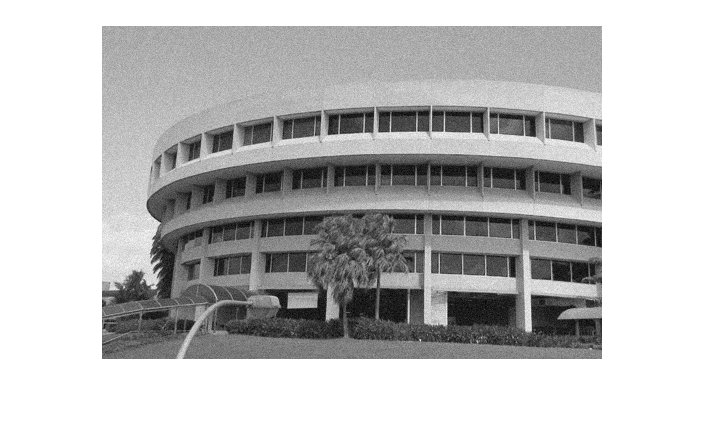

libraryGaussianNoiseImage = imread('images/ntu-gn.jpg');
imshow(libraryGaussianNoiseImage);

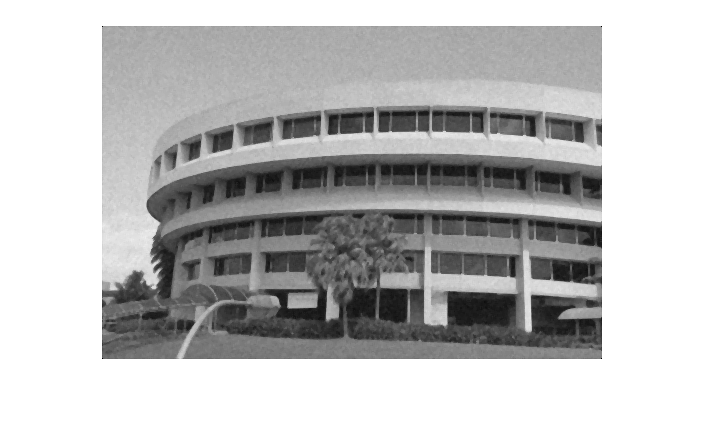


fixedGaussian1 = medfilt2(libraryGaussianNoiseImage, [3 3]);
imshow(fixedGaussian1);

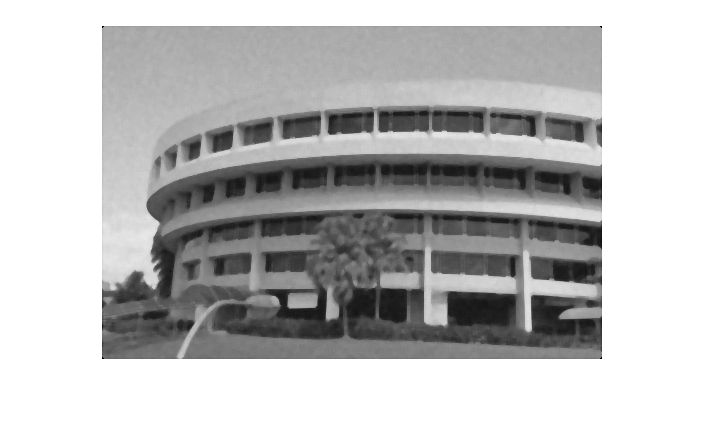


fixedGaussian2 = medfilt2(libraryGaussianNoiseImage, [5 5]);
imshow(fixedGaussian2);

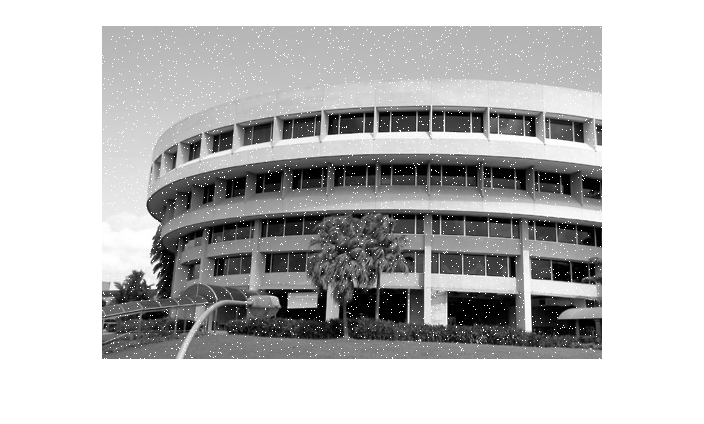


librarySpeckleNoiseImage = imread('images/ntu-sp.jpg');
imshow(librarySpeckleNoiseImage);

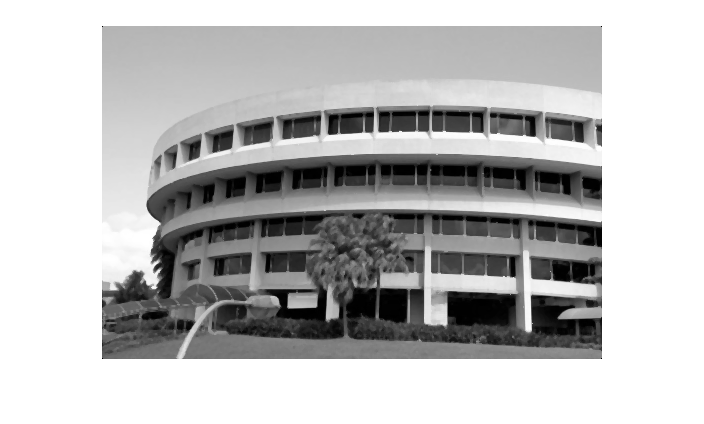


fixedSpeckle1 = medfilt2(librarySpeckleNoiseImage, [3 3]);
imshow(fixedSpeckle1);

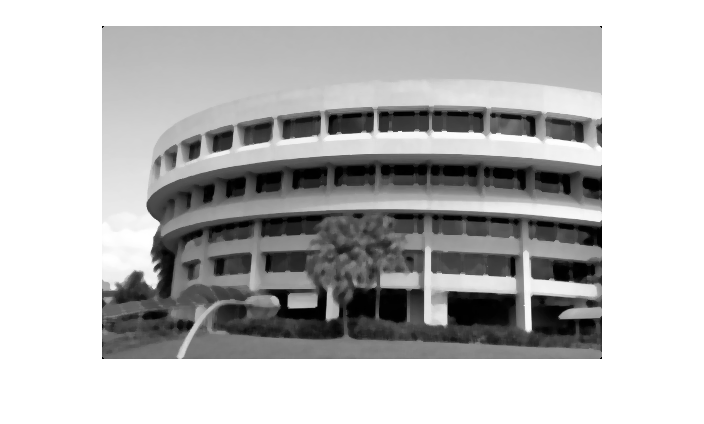


fixedSpeckle2 = medfilt2(librarySpeckleNoiseImage, [5 5]);
imshow(fixedSpeckle2);

Gaussian filtering compare with median filtering; tradeoffs: Gaussian filtering better at removing Gaussian noise, whereas median filtering better at removing speckle noise